clear; 
clc

## Setup

Assume it's a 2D problem x positive to the right and z positive up

% Constants
g = 9.8;    % gravity
m = 1;      % mass
J = 5e-2;    % moment of inertia

% Assume the trajectory is a circle with radius:
r = 10.0;
% and x and z zero at the bottom of the circle

## Minimum start velocity

The drone starts with an initial velocity towards the right. The minimum velocity is that which gives the drone enough energy to reach the top of the loop (zero thrust at the top). So at the top the centripetal force is just the weight.

Centripetal force is calculated as F = m*v^2/r. Solving: v = sqrt(m*g*r/m) = sqrt(g*r)

min_speed_top = sqrt(g*r)

min_speed_top = 9.8995

Assuming no drag, energy is conserved. The energy at the top is the kinetic energy plus the potential energy

KE_l = 1/2*m*v^2

PE = m*g*h

min_omega_top = min_speed_top/r;
min_KE_l_top = 0.5*m*min_speed_top^2;
PE_top = m*g*(2*r);
min_E = min_KE_l_top + PE_top;

At the bottom, the potential energy is zero so min_E = min_KE_l_bottom = 0.5*m*min_speed_bottom^2 . Solving:

min_speed_bottom = sqrt(2*min_E/(m))

min_speed_bottom = 22.1359

## Finding thrust and torque

Let's say the start velocity is then something larger than that

s0 = 1 * min_speed_bottom + 2;
% the energy is then
E = 0.5*m*s0^2;

It would be nice to write the speed as a function of z so that from that we can compute the time vector.

For this we can continue to use conservation of energy. E = KE_l + PE = 0.5*m*speed^2 + m*g*z.

Solving: speed = sqrt(2*(E-m*g*z)/m)

Let's make a z vector and compute the speed and omega

z_raw = r*(1-cos(linspace(0,pi,500)));
speed_raw = sqrt(2*(E-m*g*z_raw)/m);
omega_raw = speed_raw/r;

From omega and z we can compute the time vector:

theta_raw = acos((r-z_raw)/r);
t_raw = [0,cumsum(diff(theta_raw)./omega_raw(1:end-1))];

Let's now compoute a time vector with constant dt's

t = linspace(0,t_raw(end),1000);
omega = interp1(t_raw,omega_raw,t);
speed = interp1(t_raw,speed_raw,t);

And complete the other half of the circle

t = [t,t(2:end)+t(end)];
omega = [omega,flip(omega(1:end-1))];
speed = [speed,flip(speed(1:end-1))];

theta = cumtrapz(t,omega);
x = r*sin(theta);
z = r*(1-cos(theta));

Now let's plot things

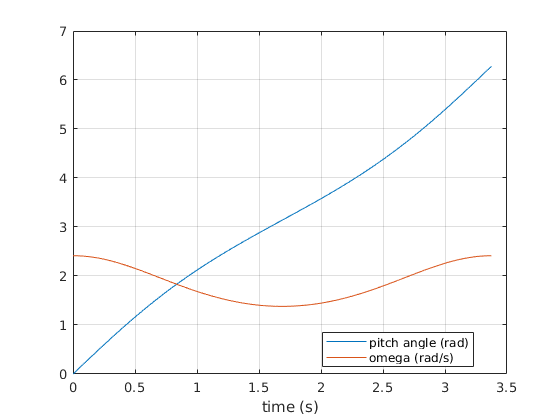

figure
plot(t,theta); hold on
plot(t,omega); hold off
grid on
xlabel('time (s)')
legend({'pitch angle (rad)','omega (rad/s)'},'location','best')

**Note that omega has to start at non-zero!**

We can now compute the centripetal force vector in body frame

f_centp = m*r*omega.^2;

The thrust + gravity should equal that force, so the thrust in world frame is

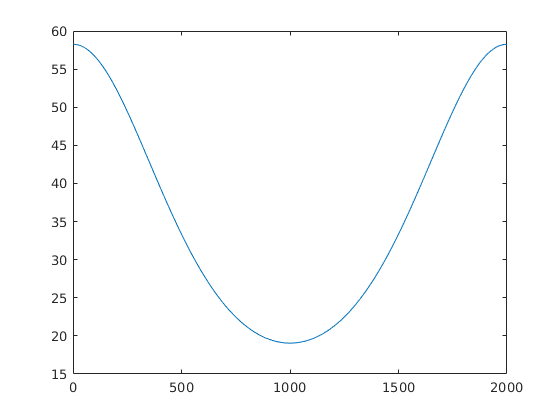

thrust_world = [-f_centp.*sin(theta); f_centp.*cos(theta)];
figure
plot(vecnorm(thrust_world)')

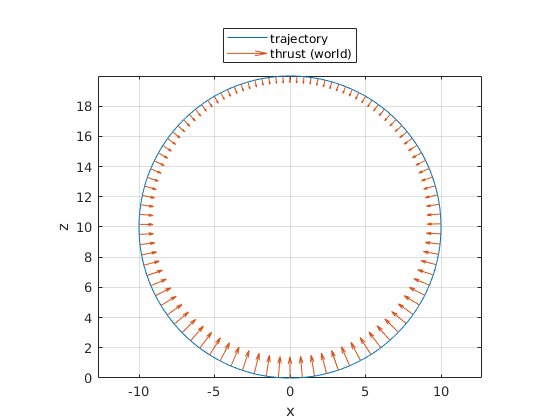


figure
plot(x,z); hold on
axis equal
grid on
xlabel('x'); ylabel('z')
qmask = 1:20:length(t);
quiver(x(qmask),z(qmask),thrust_world(1,qmask),thrust_world(2,qmask),0.5); hold off
legend({'trajectory','thrust (world)'},'location','northoutside')

And the pitch is determined by the thrust direction. **Note that the pitch is not tangential because of gravity.**

pitch = unwrap(atan2(-thrust_world(1,:),thrust_world(2,:)));
pitch_rate = diff(pitch)./diff(t);
alpha = diff(pitch_rate)./diff(t(1:end-1));
tau = J*alpha;

Let's plot the pitch and derivatives

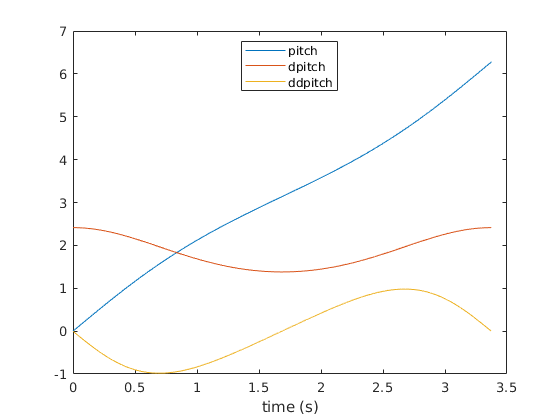

figure
plot(t(1:end),pitch); hold on
plot(t(1:end-1),pitch_rate)
plot(t(1:end-2),alpha); hold off
xlabel('time (s)')
legend({'pitch','dpitch','ddpitch'},'location','best')

2D simulation

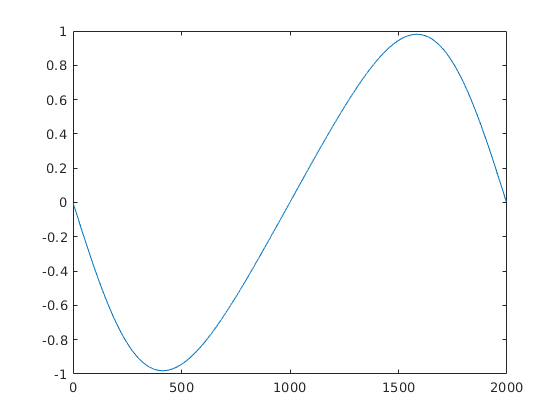

state(1).pos = [0,0]';
state(1).vel = [s0,0]';
state(1).pitch = 0;
state(1).prate = pitch_rate(1);
vel_world    = [(speed.*cos(theta))' (speed.*sin(theta))'];
acc_world    = diff(vel_world)'./diff(t);
acc_world(2,:) = acc_world(2,:) + g;
thrust_world = m * acc_world;
thrust = vecnorm(thrust_world);


for k = 2:length(pitch_rate)
    dt = t(k)-t(k-1);
    thrust_ = [thrust(k)*(-sin(state(k-1).pitch)); thrust(k)*cos(state(k-1).pitch)] ;
    state(k).vel = state(k-1).vel + (thrust_/m - [0; g])*dt;
    state(k).pos = state(k-1).pos + 1/2*(state(k-1).vel+state(k).vel)*dt;
    state(k).prate = state(k-1).prate + dt*tau(k-1)/J;
    state(k).pitch = state(k-1).pitch + 1/2*(state(k-1).prate + state(k).prate)*dt;
end
n = length(state);
pos = zeros(n,2);
pitch = zeros(n,1);
for i = 1:n
    pos(i,:) = state(i).pos';
    pitch(i) = state(i).pitch;
end

figure
plot(tau/J)

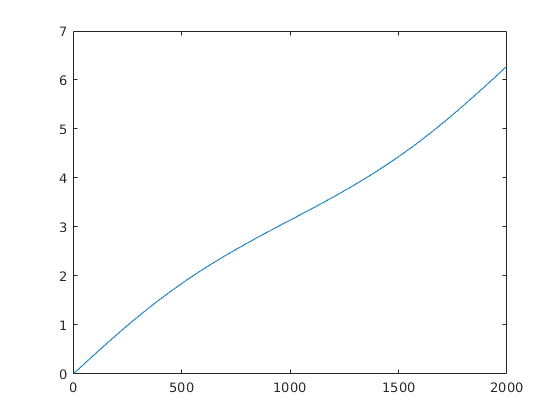


figure
plot(pitch)

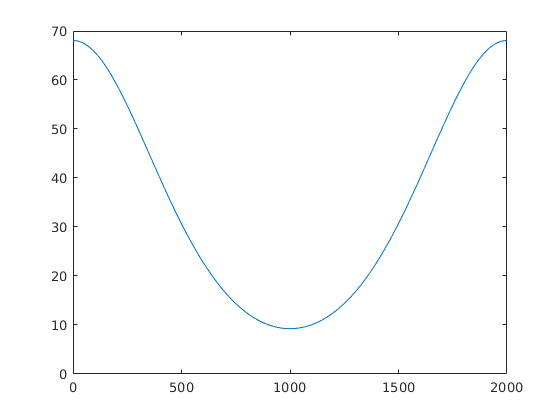


figure
plot(thrust)

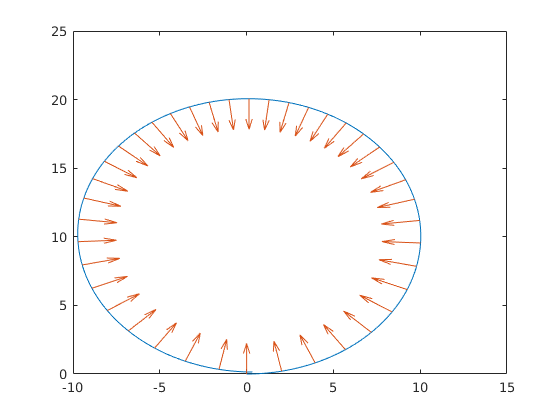


figure
plot(pos(:,1),pos(:,2)); hold on
qmask = 1:50:n;
quiver(pos(qmask,1),pos(qmask,2),-sin(pitch(qmask)),cos(pitch(qmask)),0.5); hold off